# **Tutorial 5**: a short course on TITOP (Two-Input Two-Output Ports) models

 *by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## Foreword

This tutorial is focused on the Two-Input Two-Ouput ports modelling approach and was written at the very beginning of the `SDTlib `development. The TITOP approach initially aimed to build, in a modular fashion, the dynamic model of flexible multibody systems, that is, the transfer between accelerations and forces, and its inverse. This new version of the `SDTlib` library now includes the motion vector instead of just the acceleration dual vector. The $18$-component (6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions) motion vectors is  defined in [here](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')). Nevertheless this tutorial is kept to better understand the basis principle of the TITOP approach.

## 1. Illustration in the single-axis case

### 1.1. Elementatry TITOP model of the spring-mass system

The reader is advised to read the tutorial 1: [***Introduction***](matlab:open('../Tutorial1/tutorial1.html')) first

Let us consider the spring-mass system $\mathcal A$ between points $P$ and $C$ depicted in the following Figure.  Only motions along $\mathbf x$-axis are considered. 

                            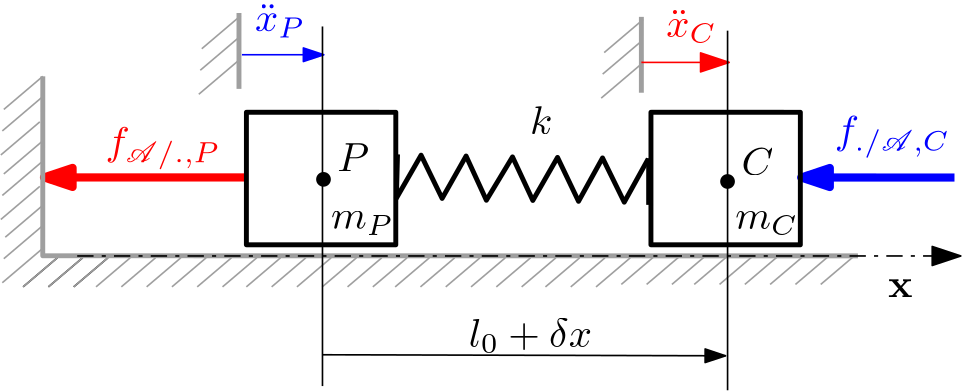

$k$, $m_P$, $m_C$ are the stiffness, the mass attached to the point $P$ and the mass attached to the point $C$ of the system $\mathcal A$, respectively. 

The objective is to compute the dynamic model $Z(\mathrm s)$ of $\mathcal A$ between 2 inputs (in blue):

- the force $f_{./\mathcal A,C}$ applied by the external world on $\mathcal A$ at the point $C$,

- the inertial acceleration $\ddot x_P$ prescribed at the point $P$,

and 2 outputs (in red)

- the inertial acceleration $\ddot x_C$ at the point $C$,

- the force $f_{\mathcal A/.,P}$ applied by $\mathcal A$ on the external world at the point $P$.

Only variations around the equilibrium conditions are considered. $\delta x$ is the variation on the length of the vector $\overrightarrow{PC}$ w.r.t its length $l_0$ at rest. The equilibrium conditions are: $x_P=cte$, $x_C=x_p+l_0$, $\dot x_p=\dot x_C=0$.

The *Newton* principle applied on each of the 2 masses leads to:

- 
$$m_P\ddot x_p=-f_{\mathcal A/.,P}+k\delta x$$


- $m_C\ddot x_C=f_{./\mathcal A,C}-k\delta x$.

Considering that $\delta \ddot x=\ddot x_C-\ddot x_P$, a state space representation of $Z(\mathrm s)$, associated to the state vector $\mathbf x=[\delta x\quad \delta\dot x]^T$, reads:


$$\left[\begin{array}{c}\delta \dot x\\\delta \ddot x\end{array}\right]=\left[\begin{array}{cc} 0 & 1 \\ -\frac{k}{m_C} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} 0 & 0  \\ \frac{1}{m_C} & -1\end{array}\right]\left[\begin{array}{c}f_{./\mathcal A,C} \\ \ddot x_P\end{array}\right]$$


$\left[\begin{array}{c}\ddot x_C\\ f_{\mathcal A/.,P}\end{array}\right]=\left[\begin{array}{cc} -\frac{k}{m_C} & 0 \\ k & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} \frac{1}{m_C} & 0  \\ 0 & -m_P\end{array}\right]\left[\begin{array}{c}f_{./\mathcal A,C} \\ \ddot x_P\end{array}\right]$,

and the $2\times 2$ transfer matrix $Z(\mathrm s)$ reads:

$\left[\begin{array}{c} \ddot X_C(\mathrm s) \\ F_{\mathcal A/.,P}(\mathrm s) \end{array}\right] = \underbrace{\frac{\left[\begin{array}{cc} \mathrm s^2 &  k \\ k & -m_Pm_C(\mathrm s ^2+\omega_{f}^2) \end{array}\right]}{m_C(\mathrm s^2+\omega_{c,P}^2)}}_{Z(\mathrm s)}\left[\begin{array}{c}F_{./\mathcal A,C}(\mathrm s) \\ \ddot X_P(\mathrm s)\end{array}\right]$,

with:

- $\omega_{f}=\sqrt{\frac{k(m_P+m_C)}{m_Pm_C}}$ is the free frequency of $\mathcal A$,

- $\omega_{c,P}=\sqrt{\frac{k}{m_C}}$ is the cantilever frequency  of $\mathcal A$ when it is cantilevered at point $P$.

The TITOP model $Z(\mathrm s)$ can also be represented by a SIMULINK block diagram model, depicted in the next figure

    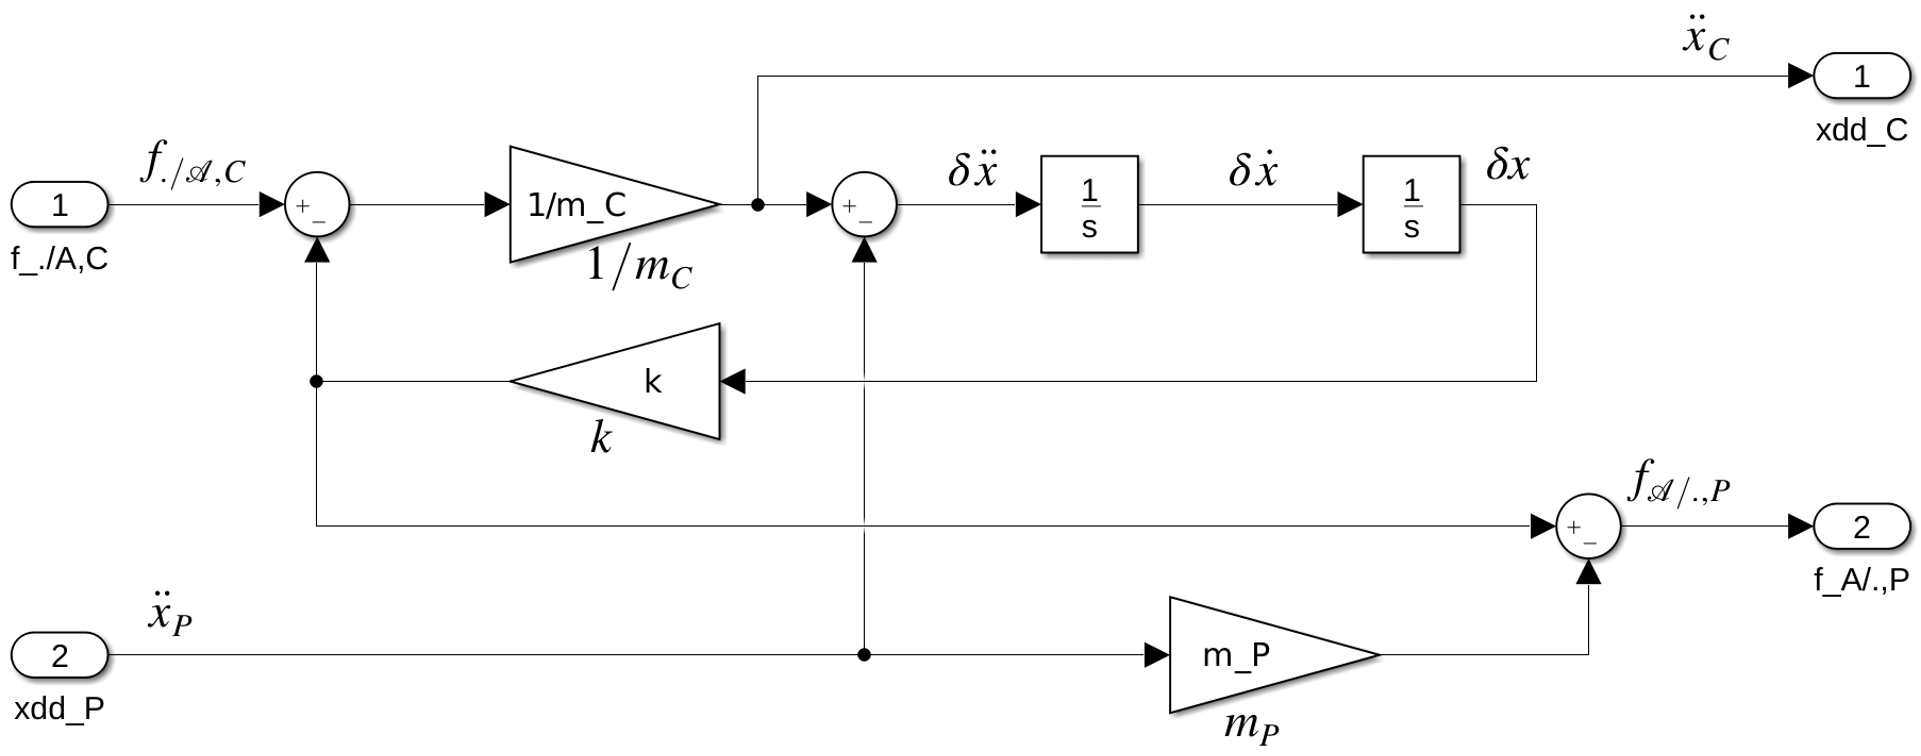

 and embbeded in a masked sub-system:

                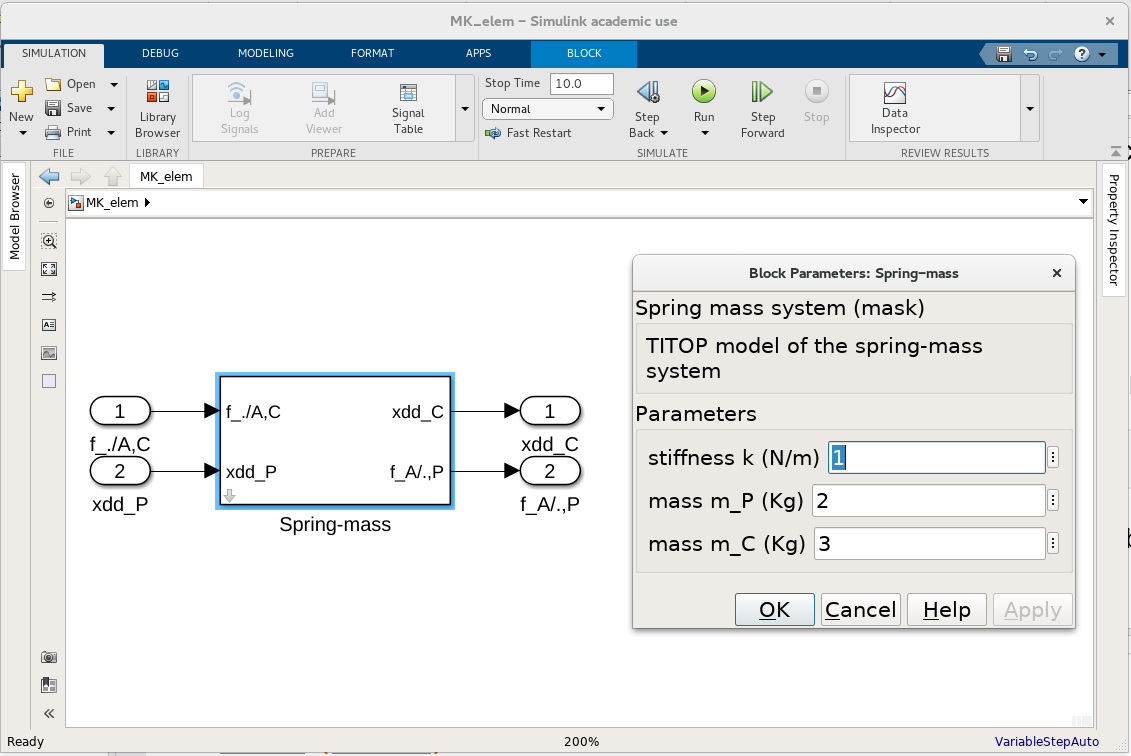

**Numerical application: **$k=1\,(Nm)$, $m_P=2\;(Kg)$, $m_C=3\,(Kg)$.

MK_elem
Z=linearize('MK_elem');

Note that the interest of the block-diagram representation, w.r.t. to the state space or transfer matrix representation is that the numbers of occurences of the 3 mechanical parameters of $\mathcal A$ ( $k$, $m_P$, $m_C$) are minimized: each parameters is associated to a single gain. Thus the uncertain system which can be derived from this SIMULINK model considering uncertain parameters for $k$, $m_P$, $m_C$ is guarranteed to be mininal in terms of order and parametric occurences.

### 1.2. Channel (port) inversion

The open-loop dynamics of the model $Z(\mathrm s)$, i.e. when the 2 inputs ( $f_{./\mathcal A,C}$ and $\ddot x_P$) are null, corresponds to the **clamped at **$P$** / free at **$C$boundary conditions, i.e: the roots of $\mathrm s^2+\omega_{c,P}^2$. 

damp(Z)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 5.77e-01i     0.00e+00       5.77e-01           Inf       
  0.00e+00 - 5.77e-01i     0.00e+00       5.77e-01           Inf       


Since $Z(\mathrm s)$ is a square ( $2\times2$) system with an invertible direct-freedthrough, it is possible to inverse $1$ or $2$ input/output channel(s) :

- the channel # 1 is the channel from $f_{./\mathcal A,C$ to $\ddot x_C$,

- the channel # 2 is the channel from $\ddot x_P$ to $f_{\mathcal A/.,P}$.

That can be done thanks to the function `invio`` of the`` SDTLIB.` See also:

web docInvio.html -new

Let us note $Z^{-1_{\mathbf I}}(\mathrm s)$the model $Z(\mathrm s)$ where the channels numbered in the vector of indexes $\mathbf I$ are inverted, then, considering the state-space realization previously defined:

- $Z^{-1_{2}}(\mathrm s)$ is the **free at **$P$** / free at **$C$ model with the state space representation:


$$\left[\begin{array}{c}\delta \dot x\\\delta \ddot x\end{array}\right]=\left[\begin{array}{cc} 0 & 1 \\ -\frac{k}{m_C}-\frac{k}{m_P} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} 0 & 0  \\ \frac{1}{m_C} & \frac{1}{m_P}\end{array}\right]\left[\begin{array}{c}f_{./\mathcal A,C} \\ f_{\mathcal A/.,P}\end{array}\right]$$


$\left[\begin{array}{c}\ddot x_C\\ \ddot x_P\end{array}\right]=\left[\begin{array}{cc} -\frac{k}{m_C} & 0 \\ \frac{k}{m_P} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} \frac{1}{m_C} & 0  \\ 0 & -\frac{1}{m_P}\end{array}\right]\left[\begin{array}{c}f_{./\mathcal A,C} \\ f_{\mathcal A/.,P}\end{array}\right]$,

            and its open-loop dynamics,  i.e. when the 2 inputs ( $f_{./\mathcal A,C}$ and $f_{\mathcal A/.,P}$) are null, corresponds to the roots of $\mathrm s^2+\omega_f^2$,

damp(invio(Z,2))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 9.13e-01i     0.00e+00       9.13e-01           Inf       
  0.00e+00 - 9.13e-01i     0.00e+00       9.13e-01           Inf       


- $Z^{-1_{[1,2]}}(\mathrm s)=Z^{-1}(\mathrm s)$ is the **free at **$P$** / clamped at **$C$model with the state space representation:


$$\left[\begin{array}{c}\delta \dot x\\\delta \ddot x\end{array}\right]=\left[\begin{array}{cc} 0 & 1 \\ -\frac{k}{m_P} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} 0 & 0  \\ 1 & \frac{1}{m_P}\end{array}\right]\left[\begin{array}{c}\ddot x_C\\ f_{\mathcal A/.,P}\end{array}\right]$$


$\left[\begin{array}{c}f_{./\mathcal A,C} \\ \ddot x_P\end{array}\right]=\left[\begin{array}{cc} k & 0 \\ \frac{k}{m_P} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} m_C & 0  \\ 0 & -\frac{1}{m_P}\end{array}\right]\left[\begin{array}{c}\ddot x_C\\ f_{\mathcal A/.,P}\end{array}\right]$,

            and its open-loop dynamics,  i.e. when the 2 inputs ( $\ddot x_C$ and $f_{\mathcal A/.,P}$) are null, corresponds to the roots of $\mathrm s^2+\omega_{c,C}^2$  where $\omega_{c,C}=\sqrt{\frac{k}{m_P}}$ is the cantilever frequency  of $\mathcal A$ when it is cantilevered at point $C$,

damp(inv(Z))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 7.07e-01i     0.00e+00       7.07e-01           Inf       
  0.00e+00 - 7.07e-01i     0.00e+00       7.07e-01           Inf       


- $Z^{-1_{1}}(\mathrm s)$ is the **clamped at **$P$** / clamped at **$C$model with the state space representation:

$\left[\begin{array}{c}\delta \dot x\\\delta \ddot x\end{array}\right]=\left[\begin{array}{cc} 0 & 1 \\ 0 & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} 0 & 0  \\ 1 & -1\end{array}\right]\left[\begin{array}{c} \ddot x_C \\ \ddot x_P\end{array}\right]$,


$$\left[\begin{array}{c} f_{./\mathcal A,C} \\ f_{\mathcal A/.,P}\end{array}\right]=\left[\begin{array}{cc} k & 0 \\ k & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} m_C & 0  \\ 0 & -m_P\end{array}\right]\left[\begin{array}{c}\ddot x_C \\ \ddot x_P\end{array}\right]$$


            and its open-loop dynamics,  i.e. when the 2 inputs ( $\ddot x_C$ and $\ddot x_p$) are null, corresponds to the roots of $\mathrm s^2$.

damp(invio(Z,1))

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00           Inf       
  0.00e+00    -1.00e+00       0.00e+00           Inf       


It is surprising and interesting to note that the dynamics of $Z^{-1_{1}}(\mathrm s)$ corresponds to a double integrator $\mathrm s^2$. Indeed, the two inputs of $Z^{-1_{1}}(\mathrm s)$ are $\ddot x_C$ and $\ddot x_P$. Obviously, the steady state response of $Z^{-1_{1}}(\mathrm s)$to  2 independent steps on these 2 inputs creates infinite outputs (the forces $f_{./\mathcal A,C}$ and $f_{\mathcal A/., P}$). Thus the DCgain of $Z^{-1_{1}}(\mathrm s)$is:

$Z^{-1_{1}}(0)=\left[\begin{array}{cc}-\infty & +\infty \\ -\infty & +\infty\end{array}\right]$.

If now it is imposed that the 2 inputs must be equal: $\ddot x_P=\ddot x_C=\ddot x_\mathcal A$, then the 2 integrators must be reduced such that the transfer from $\ddot x_\mathcal A$ to $f_{./\mathcal A,C$ and $f_{\mathcal A/.,P}$ is:

$\left[\begin{array}{c} f_{./\mathcal A,C} \\ f_{\mathcal A/.,P}\end{array}\right]=\left[\begin{array}{c} m_C\\ -m_P\end{array}\right]\ddot x_{\mathcal A}$.

Indeed, one can recover this resuts using the function `minreal`` (minimal realization)`:

minreal(invio(Z,1)*[1;1])

2 states removed.

ans =
 
  D = 
       u1
   y1   3
   y2  -2
 
Static gain.



One can also consider the "dual" property which consists to consider a single output $f_{./\mathcal A}=f_{./\mathcal A, C}-f_{\mathcal A/.,P}$(i.e. the total force applied to $\mathcal A$ by the external world) in order to recover the quite obvious static model:

$f_{./\mathcal A}=[m_C\quad m_P]\left[\begin{array}{c}\ddot x_C \\ \ddot x_P\end{array}\right]$:

minreal([1 -1]*invio(Z,1))

2 states removed.

ans =
 
  D = 
       u1  u2
   y1   3   2
 
Static gain.



**Conclusion**: the main interest of the TITOP model $Z(\mathrm s)$ is that it can be used to model the system $\mathcal A$ for any arbitrary boundary conditions at its tips $P$ and $C$, thanks to simple channel operations.

### 1.3. Assembling open-kinematic chains of spring-mass systems

The previous conclusion works not only for clamped or free boundary conditions but also for any dynamical systems connected to $\mathcal A$ at the point $P$ or at the point $C$.

Indeed, let us consider the systems $\mathcal S$ depicted in the following Figure and composed of 4 spring-mass sub-systems $\mathcal A_i$, $i=1,\cdots 4$. The objective is to find  the model between the input  $u\,(N)$, a force (thurst) applied to the point $P_1$, and the variations of positions of the points $P_1$ ( $\delta x_{P_1}$) and $C_4$ ( $\delta x_{C_4}$).

    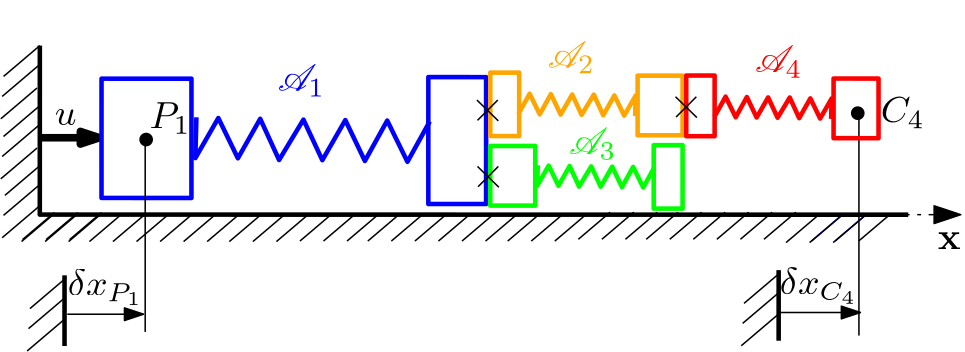

For each sub-system $\mathcal A_i$, let us denote:

- $P_i$, $C_i$:  the 2 points at the tips of $\mathcal A_i$,

- $k_i,\;m_{P_i},\;m_{C_i}$:  its  3 mechanical parameters,

- $Z_i(\mathrm s)$: its TITOP model associated to state vector $\mathbf x_i=[\delta x_i\quad \delta\dot x_i]^T$.

**Numerical application:**


$$\begin{array}{l | l | l | l |} i \quad  & k_i\,(N/m) & m_{P_i}\,(Kg) & m_{C_i}\,(Kg) \\ \hline \\ 1 & 1 & 2 & 3 \\ \hline 2 & 4 & 5 & 6\\ \hline 3 & 7 & 8 & 9 \\ \hline 4 & 10 & 11 & 12 \\ \hline \end{array}$$


The model of the whole system $\mathcal S$can then be defined by the interconnection of the 4 blocks  $Z_1^{-1_2}(\mathrm s)$,  $Z_2(\mathrm s)$, $Z_3(\mathrm s)$ and $Z_4(\mathrm s)$ according to the following SIMULINK model ( file `MK_elem_x4.xls`) depicted in the next Figure and considering the action/re-action relations:

$u=-f_{\mathcal A_1/.,P_1}$;   $f_{./\mathcal A_1,C_1}=f_{\mathcal A_2/.,P_2}+f_{\mathcal A_3/.,P_3}$;   $f_{./\mathcal A_2,C_2}=f_{\mathcal A_4/.,P_4}$;   $f_{./\mathcal A_3,C_3}=f_{./\mathcal A_4,C_4}=0$,

and the accelaration constraints: $\ddot x_{P_2}=\ddot x_{P_3}=\ddot x_{C1}$, $\ddot x_{P_4}=\ddot x_{C_2}$.

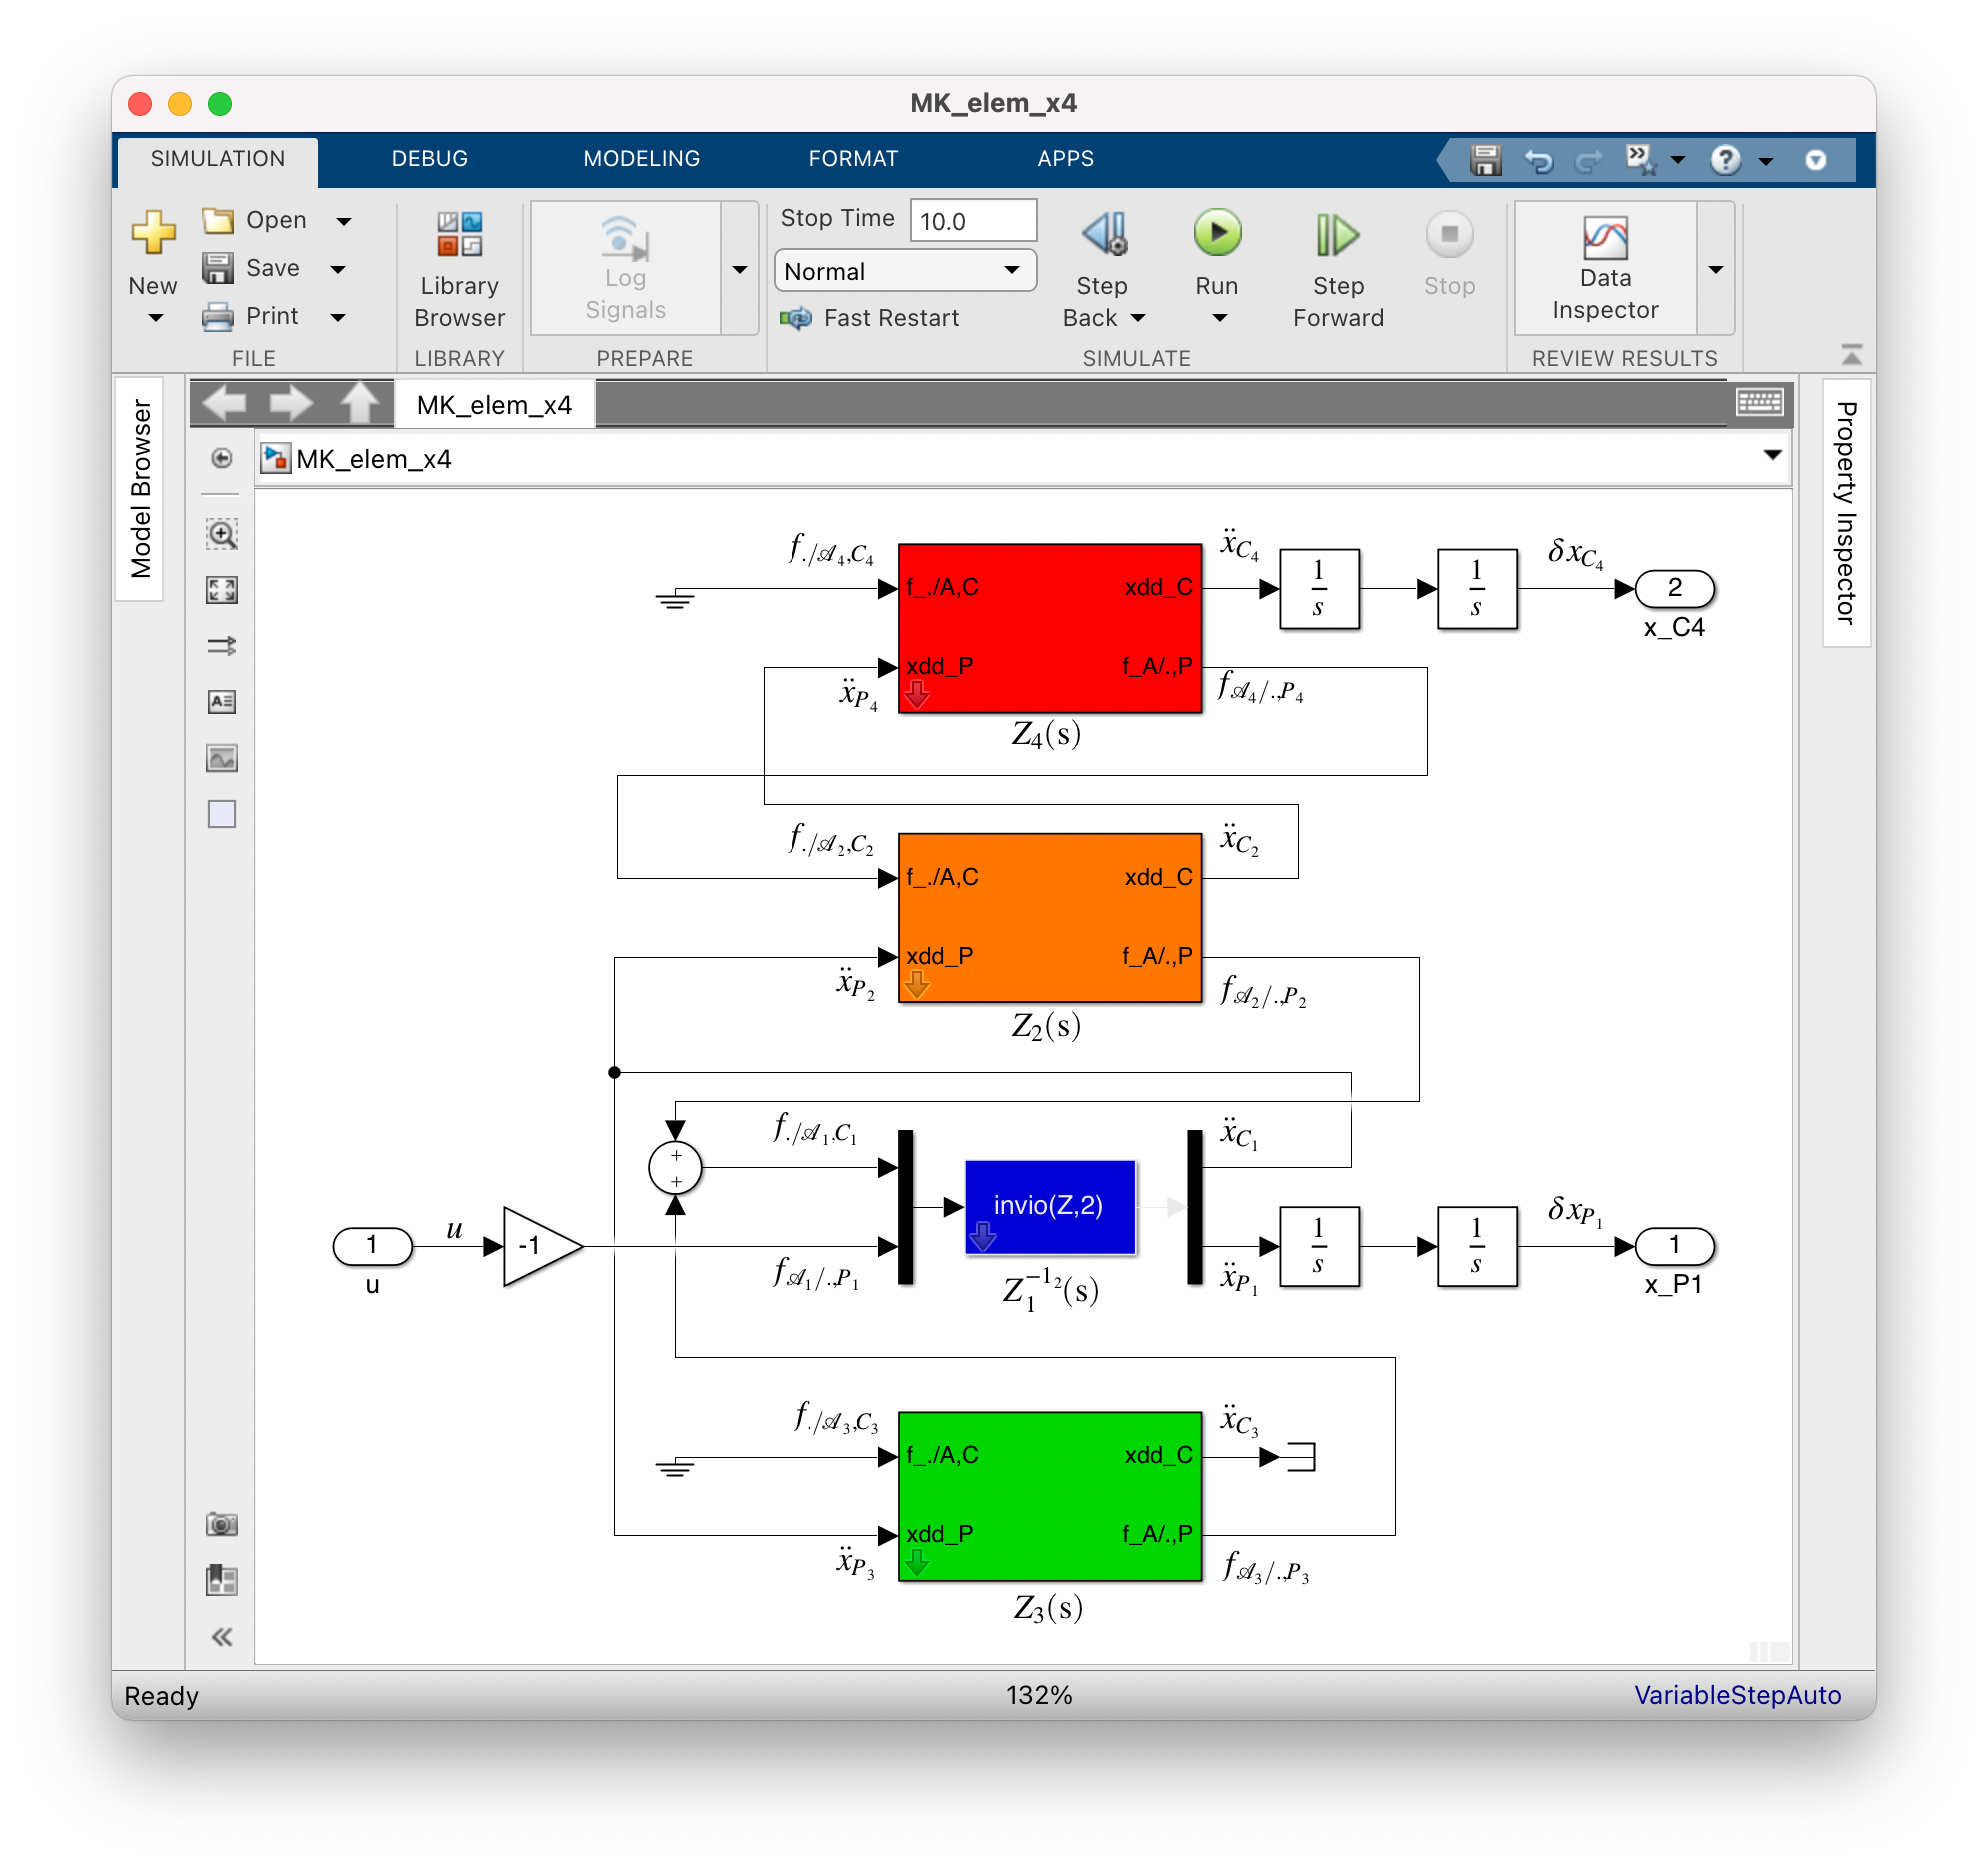    

Finally: 2 double integators was added on $\ddot x_{P_1}$ and $\ddot x_{C_4}$ to obtain the position outputs $\delta x_{P_1}$ and $\delta x_{C_4}$ . Note that one of the 2 double integrators is non-miminal and can be removed considering the geometric constraints between the outputs and the internal state variables: 

- $\delta x_{C_4}=\delta x_{P_1}+\delta x_1+\delta x_2+\delta x_4$,

- $\delta \dot x_{C_4}=\delta \dot x_{P_1}+\delta \dot x_1+\delta \dot x_2+\delta \dot x_4$.

Therefore, it is recommended to use `minreal` or `sminreal` on the linear models derived from the SIMULINK models and the `linmod` or `linearize` functions. Note that in the various examples provided in the tutorials, the `linearize` function **sometimes provides a minimal model and sometimes a non-minimal model**:

MK_elem_x4
G=linearize('MK_elem_x4');
G=minreal(G);

2 states removed.


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.34e-08                -1.00e+00       1.34e-08        -7.44e+07    
 -1.34e-08                 1.00e+00       1.34e-08         7.44e+07    
 -5.03e-16 + 4.90e-01i     1.03e-15       4.90e-01         1.99e+15    
 -5.03e-16 - 4.90e-01i     1.03e-15       4.90e-01         1.99e+15    
  9.71e-17 + 7.27e-01i    -1.34e-16       7.27e-01        -1.03e+16    
  9.71e-17 - 7.27e-01i    -1.34e-16       7.27e-01        -1.03e+16    
  1.94e-16 + 1.15e+00i    -1.70e-16       1.15e+00        -5.15e+15    
  1.94e-16 - 1.15e+00i    -1.70e-16       1.15e+00        -5.15e+15    
  1.11e-16 + 1.27e+00i    -8.77e-17       1.27e+00        -9.01e+15    
  1.11e-16 - 1.27e+00i    -8.77e-17       1.27e+00        -9.01e

**One of the main interest in the proposed TITOP modeling approach is that the model of  a flexible multi-body system is highly structured and based on the interconnection of the TITOP models of the various flexible bodies. Each TITOP model depends only on its own mechanical parameters. Thus this approach is suitable to derive minimal LFT  model when parametric variations are taken into account.**

### 1.4. Assembling closed-kinematic chains of spring-mass systems

Let us consider the system $\mathcal S$ depicted in the following Figure and composed of 3 spring-mass sub-systems $\mathcal A_i$, $i=1,\cdots 3$. Inside the subsytem $\mathcal A_1$, a controlled force $u\,(N)$ can be applied between the 2 tips masses. The objective is to find  the model between the input  $u\,(N)$ and the variations of  acceleration $\ddot x_{P_1}$ of the point $P_1$.

        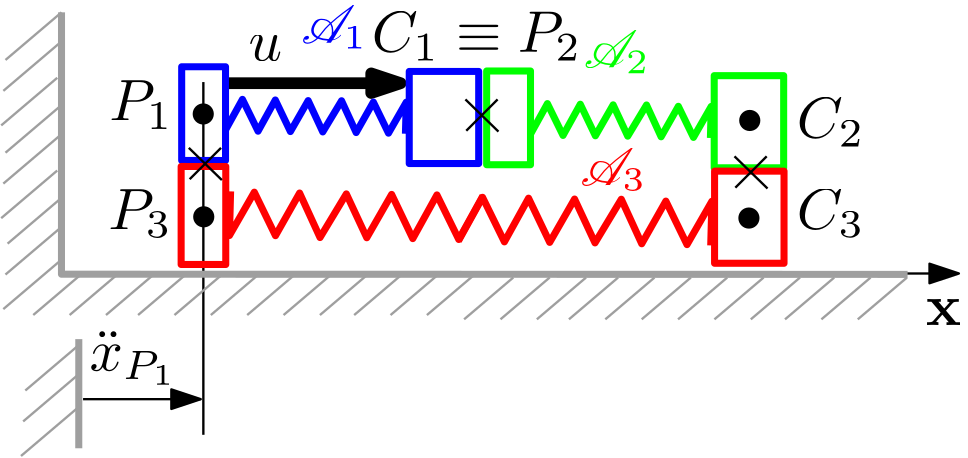

**Numerical application: **$k_i=1\,(Nm)$, $m_{P_i}=2\;(Kg)$, $m_{C_i}=3\,(Kg),\;\;\forall i=1,2,3$. Thus $Z_i(\mathrm s)=Z(\mathrm s)$, (variable` Z `in the workspace). 

Such a system is a mechanism with a closed kinematic chain since: $x_{P_1}=x_{P_3}$ and $x_{C_2}=x_{C_3}$ at any time.

The model of the whole system $\mathcal S$can then be defined by the interconnection of the 3 blocks $Z_1^{-1_2}(\mathrm s)$,  $Z_2(\mathrm s)$, and $Z_3^{-1_1}(\mathrm s)$ according to the following SIMULINK model ( file `MK_elem_cl.xls`) depicted in the next Figure and considering the action/re-action relations:

$f_{\mathcal ./A_1,P_1}=-u+f_{\mathcal A_3/.,P3}$;   $f_{./\mathcal A_1,C_1}=f_{\mathcal A_2/.,P_2}+u$;   $f_{./\mathcal A_2,C_2}=-f_{./\mathcal A_3,C_3}$,

and the acceleration constraints: $\ddot x_{P_1}=\ddot x_{P_3}$, $\ddot x_{C_2}=\ddot x_{C_3}$, and $\ddot x_{P_2}=\ddot x_{C_1}$.

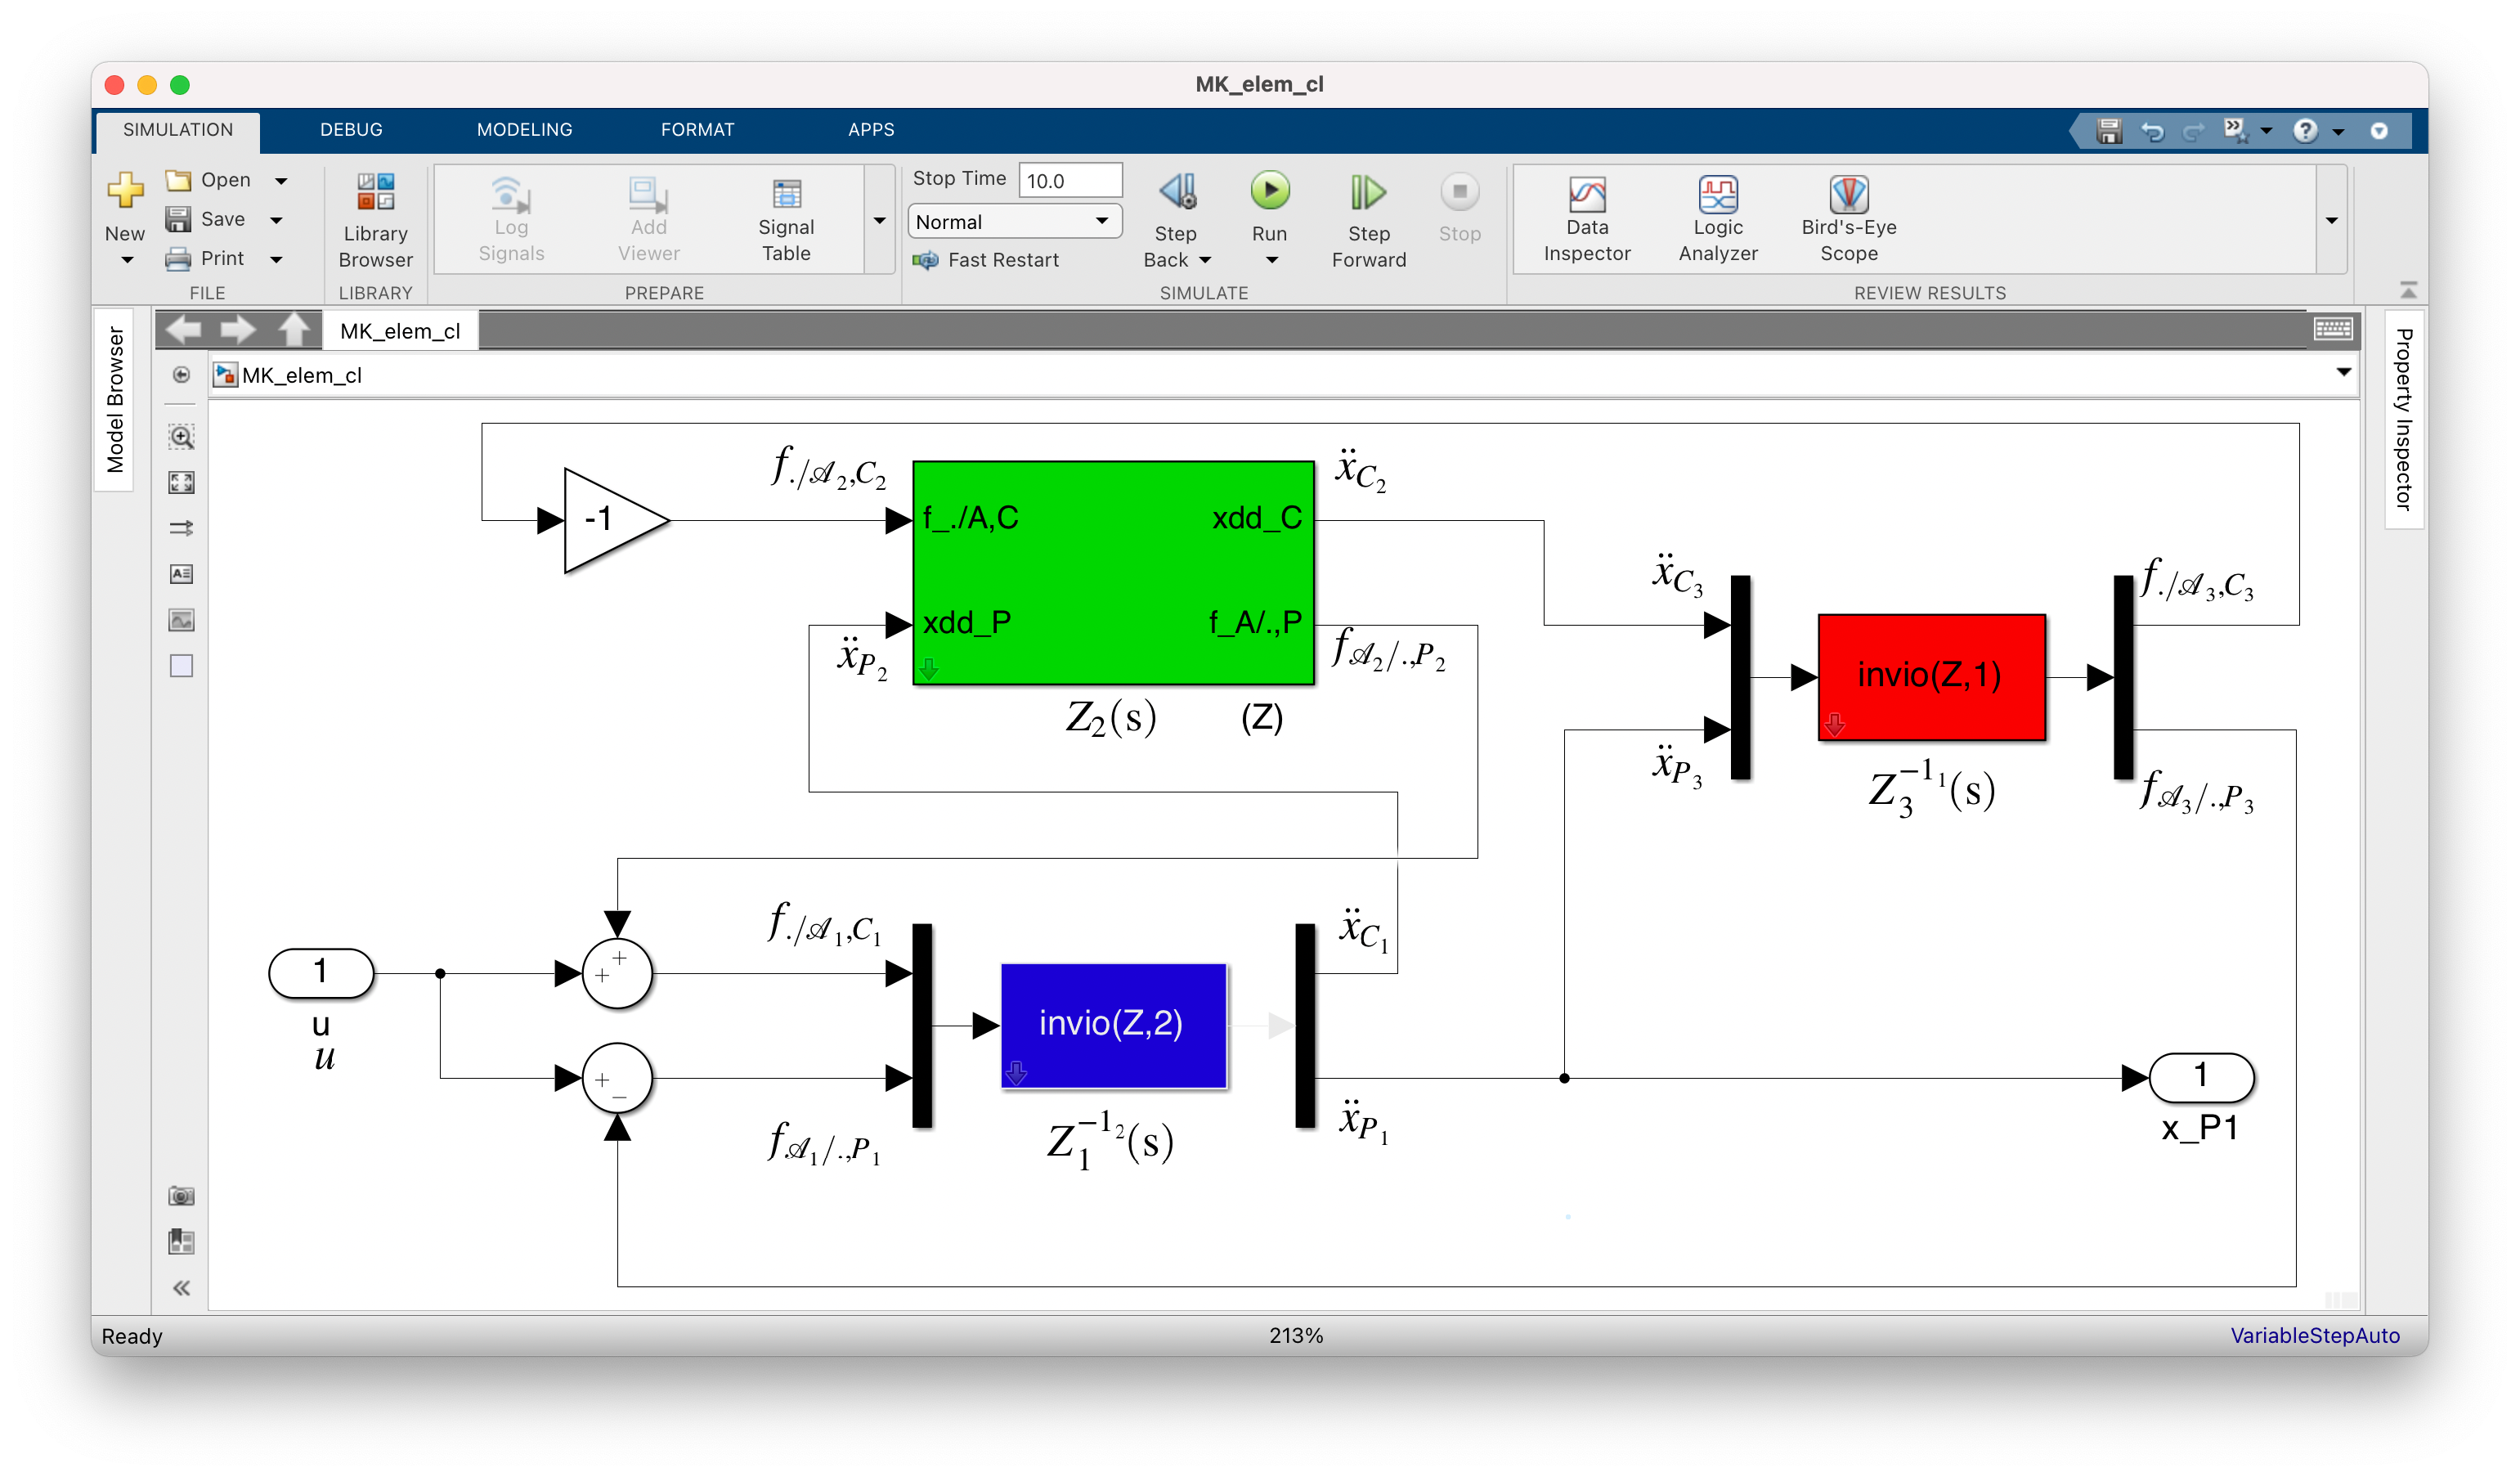

MK_elem_cl
[a,b,c,d]=linmod('MK_elem_cl');
G=ss(a,b,c,d);
% G=linearize('MK_elem_cl');
% RK: In this eample, the linmod function is preferred to the linearize function to be 
% sure to exhibit  the poles at 0.
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.89e-09                 1.00e+00       5.89e-09         1.70e+08    
  5.89e-09                -1.00e+00       5.89e-09        -1.70e+08    
  6.84e-18 + 7.38e-01i    -9.27e-18       7.38e-01        -1.46e+17    
  6.84e-18 - 7.38e-01i    -9.27e-18       7.38e-01        -1.46e+17    
 -6.46e-17 + 8.30e-01i     7.78e-17       8.30e-01         1.55e+16    
 -6.46e-17 - 8.30e-01i     7.78e-17       8.30e-01         1.55e+16    


The dyamics is characterized by 2 flexible modes  (at $0.738\,(rad/s)$ and $0.83 (rad/s)$) and 2 eigenvalues around $0$. These 2 eigenvalues corresponds to the geometric constraints between the internal state variables to maintain the kinematic chain  closed for any value of the deformation: 

- $\delta x_1+\delta x_2-\delta x_3=0$,

- $\delta \dot x_1+\delta \dot x_2-\delta \dot x_3=0$.

They can be reduced using a minimal realization of the transfer using `minreal`:

G=minreal(G);

2 states removed.


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.11e-16 + 7.38e-01i    -1.51e-16       7.38e-01        -9.01e+15    
  1.11e-16 - 7.38e-01i    -1.51e-16       7.38e-01        -9.01e+15    
  0.00e+00 + 8.30e-01i     0.00e+00       8.30e-01              Inf    
  0.00e+00 - 8.30e-01i     0.00e+00       8.30e-01              Inf    


More complex example of closed-loop mechanism involving 2D plates and several closed kinematic chains, the 4 bar mechanism and the slider-crank mechanism are proposed in the tutorial 9 [***A solar array with 3 pannels***](matlab:open('../Tutorial9/tutorial9.html'))***, *** the tutorial 11 [***The 4 bar mechanism***](matlab:open('../Tutorial11/tutorial11.html'))  and the tutorial 13 [***The slider-crank mechanism***](matlab:open('../Tutorial13/tutorial13.html')) of the **full version** of the `SDTlib`.

## 2. Six dofs case

The previous TITOP  modelling approach can be directly extented to the 6 d.o.fs case while taking into account:

- the dynamics coupling between translations and rotations due to the geometry (lever-arm effect),

- the various frames in which are described the various bodies $\mathcal A_i$ ,

- the 6 d.o.f.s behavior of the flexible modes of each bodie $\mathcal A_i$. The dynamic model of this flexible behavior can be:

-     (i) computed analytically for a body with a very simple shape: uniform beam, uniform rectangular plate,

-     (ii) provided by finite element method softwares. A NASTRAN/SIMULINK interface is available in the **full version** of the `SDTlib`. (see also the sub-library` 6 dof bodies` of the `SDTlib `and the tutorial 7 [***Cantilevered plate dynamics studied with SDTlib block NINOP Nastran body***](matlab:open('../Tutorial7/tutorial7.html')) of the full version).

### 2.1. Six d.o.fs TITOP model of a flexible body

Let us consider a flexible substructure $\mathcal{A}$ (link) connected a the parent substructure $\mathcal{P}$ at the point $P$ and to the child substructure $\mathcal{C}$at point $C$ as depicted in next Figure. $\mathcal{R}_a$ is the body frame attached to $\mathcal A$.

            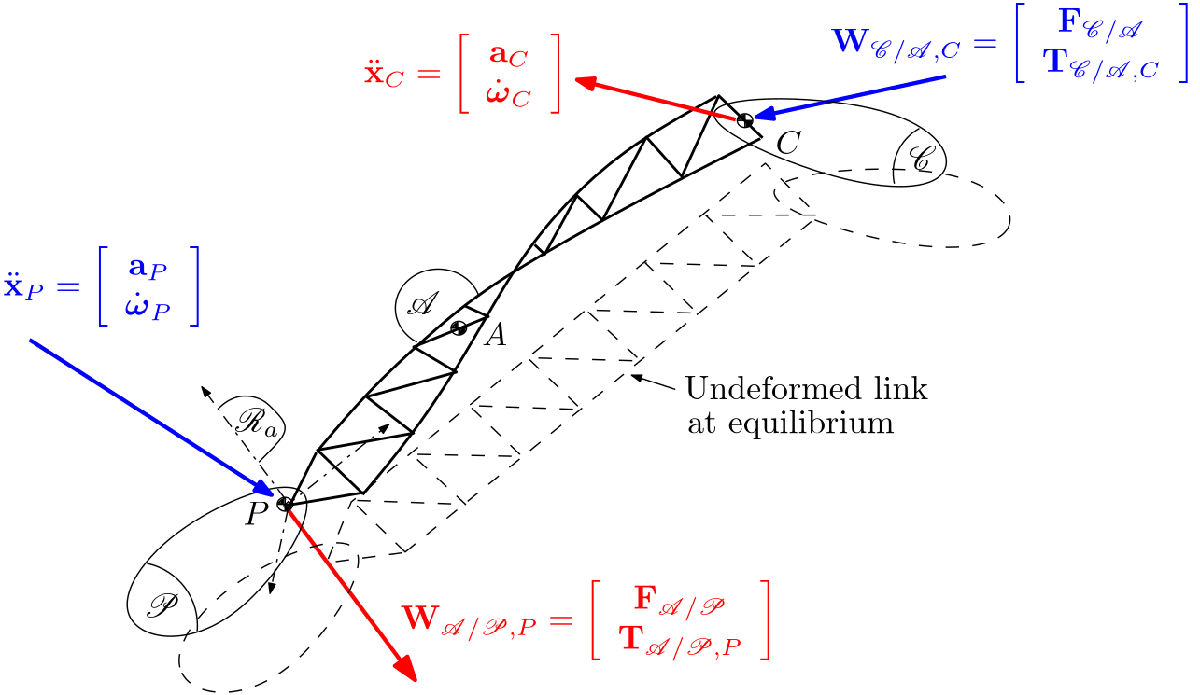

The  TITOP (Two-Input Two-Output Port) model $[\mathbf{M}_{P,C}^{\mathcal{A}}]_{\mathcal R_a}(\mathrm{s})$ is a linear dynamic model between $12$ inputs:

- the 6 components in $\mathcal{R}_a$ of the wrench $[\mathbf{W}_{\mathcal{C/A},C}]_{\mathcal R_a}=\left[ {\begin{array}{*{20}c}{ \mathbf{F}_{\mathcal{C/A}} }  \\{ \mathbf{T}_{\mathcal{C/A},C} }  \\ \end{array}} \right]_{\mathcal R_a}$ applied by the child substructure $\mathcal{C}$ to $\mathcal{A}$ at point $C$,

- the 6 components in $\mathcal{R}_a$ of the acceleration twist $[\ddot{\mathbf{x}}_P]_{\mathcal R_a}=\left[\begin{array}{c}\mathbf{a}_P\\ \dot\mathbf\omega_P \end{array}\right]_{\mathcal R_a}$ (time-derivative of the twist) of the point $P$,

and $12$ outputs:

- the 6 components in $\mathcal{R}_a$ of the acceleration twist  $[\ddot{\mathbf{x}}_C]_{\mathcal R_a}=\left[\begin{array}{c}\mathbf{a}_C\\ \dot\mathbf\omega_C \end{array}\right]_{\mathcal R_a}$ of point $C$,

- the 6 components in $\mathcal{R}_a$ of the wrench $[\mathbf{W}_{\mathcal{A/P},P}]_{\mathcal R_a}=\left[ {\begin{array}{*{20}c}{ \mathbf{F}_{\mathcal{A/P}} }  \\ { \mathbf{T}_{\mathcal{A/P},P} }  \\ \end{array}} \right]_{\mathcal R_a}$ applied by $\mathcal{A}$ to the parent substructure $\mathcal{P}$ at point $P$,

and can be represented by the block-diagram depicted in next Figure. 

                    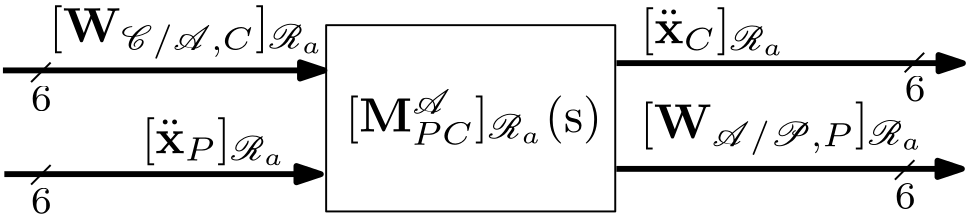

The way to obtain the TITOP model $\mathbf{M}_{P,C}^{\mathcal{A}}(\mathrm s)$ in the general case is detailled in [**AIAA 2015**](https://oatao.univ-toulouse.fr/13642/) and is based on the modal analysis of the body $\mathcal{A}$ with the **clamped at **$P$** - free at **$C$boundary conditions.  Indeed, the *Lagrange*'s formulation of dynamics leads to the generalized $2$-nd order differential equation (all the terms are projected in the frame $\mathcal R_a$, omitted for brivety):


$$\left[\begin{array}{cc}\mathbf{D}^{\mathcal{A}}_{P} & \mathbf{L}_{P}^T\\ \mathbf{L}_{P} & \mathbf{1}_{n}\end{array}\right]\left[\begin{array}{c}\ddot{\mathbf{x}}_{P}\\ \ddot{\mathbf{\eta}}\end{array}\right]+\left[\begin{array}{cc} \mathbf{0}& \mathbf{0} \\  \mathbf{0} & \mbox{diag}(2\xi_j\omega_j)\end{array}\right]\left[\begin{array}{c}\star \\ \dot{\mathbf{\eta}}\end{array}\right]+\left[\begin{array}{cc} \mathbf{0}& \mathbf{0}\\  \mathbf{0}& \mbox{diag}(\omega_j^2)\end{array}\right]\left[\begin{array}{c}\star \\ \mathbf{\eta}\end{array}\right]=\left[\begin{array}{cc}-\mathbf{I}_6 & \mathbf{\tau}_{CP}^T\\ \mathbf{0} &  \mathbf{\Phi}_{C}^T \end{array}\right]\left[\begin{array}{c}\mathbf{W}_{\mathcal{A/P},P} \\ \mathbf{W}_{\mathcal{C/A},C}\end{array}\right]$$


where:

-  $n$ is the number of flexible modes of body $\mathcal{A$ characterized by the  modal coordinates vector $\mathbf{\eta}$, the frequencies $\omega_j$ $j=1,\cdots,n$ and the damping ratio $\xi_j$, $j=1,\cdots,n$,

- $\mathbf{1}_{n}$ is the identity matrix of size $n$,

- $\mathbf{L}_{P}$ is the $n\times 6$ modal participation factor matrix of the body at point $P$, 

- $\mathbf{\Phi}_{C}$ is the  $6\times n$ projection matrix of the $n$ clamped-free modal shapes on the $6$ d.o.fs at point $C$,

- $\mathbf{\tau}_{CP}$ is the "rigid'' kinematic model between point $C$ and $P$: $\mathbf{\tau}_{CP}=\left[\begin{array}{cc} \mathbf{1}_3  & (^*\overrightarrow{CP})\\ \mathbf{0}_{3\times 3} & \mathbf{1}_3  \\ \end{array}\right]$ where $(^*\overrightarrow{CP})$ is the skew-symmetric matrix associated to vector from $C$ to $P$,

- $\mathbf{D}^{\mathcal{A}}_{P}$ is the $6 \times 6$  rigid mass model of the body at point $P$. $\mathbf{D}^{\mathcal{A}}_P=\mathbf\tau_{AP}^T\left[\begin{array}{cc}m^{\mathcal{A}}\mathbf{1}_3 & \mathbf{0}_{3\times 3}\\ \mathbf{0}_{3\times 3} & [\mathbf{I}^{\mathcal{A}}_A] \end{array}\right]\mathbf\tau_{AP}$ where $A$, $m^{\mathcal A}$ and $\mathbf I^{\mathcal A}_A$  are the centre of mass, the mass and the inertia tensor at $A$, respectively.

The acceleration twist $\mathbf{\ddot{x}}_{C}$ at point $C$ reads:

$\ddot{\mathbf{x}}_{C}=[\mathbf{\tau}_{CP}\quad \mathbf{\Phi}_{C}]\left[\begin{array}{c}\ddot{\mathbf{x}}_{P}\\ \ddot{\mathbf{\eta}}\end{array}\right]$.

These equations can be expressed with a block-diagram representation and thus a SIMULINK model as it is proposed in the `SDTlib`.  All the required data ( $n$, $\omega_j$, $\xi_j$, $\mathbf L_P$, $\mathbf \Phi_C$, $\overrightarrow{CP}$, $\overrightarrow{AP}$, $m^{\mathcal A}$, $\mathbf I^{\mathcal A}_A$) can be extracted from the `NASTRAN` file of the body $\mathcal A$ (files `***.bdf` and` ***.f06`)  thanks to the block `N ports Nastran body` of the sub-library `6 DOF `bodies (available with the **full version** of the `SDTlib`). 

Finally, the TITOP model  of a flexible body can be easily extended to NINOP (N-Input, N-Output Ports) model, considering several child points $C_1$, $C_2$, ... .

For a uniform beam and a uniform rectangular plate, all the required data are derived analytically from the geometry and material characteristics in the blocks `TITOP flexible beam` and `NINOP flexible plate`. See also:

web DocBeam.html -new
web DocPlate_joly.html -new

Rigid bodies can also be handled under this formalism thanks to the block `Multi-port rigid body`. See also:

web Docmultiportrigidbody.html -new

### 2.2 TITOP model of a revolute or prismatic joint

#### 2.2.1. Revolute joint

The body $\mathcal A$ can be linked to the parent body $\mathcal P$ at point $P$ through a revoute joint, characterized by the axis direction $\mathbf{r_a}$ (unitary vector expressed in the body frame $\mathcal A$: $\mathcal R_a$) and an angular configuration $\theta$. Then, the TITOP model of the revolute joint $\left[\mathbf{M}^{r}_{P}\right]^{\mathcal R_a}_{\mathcal R_p}(\mathrm{s},\theta)$ depicted in the next Figure can be used for the assembly of the multi-body system. This block is a $13\times 13$ transfer with:

- the $12\times 12$ TITOP transfer between the wrenches and the accelerations twists at the input shaft (and thus expressed in the frame $\mathcal R_p$) and at the output shaft (and thus expressed in the frame $\mathcal R_a$). $\mathcal R_a$ and $\mathcal R_p$ are aligned when $\theta=0$,

- the SISO channel from the torque $C_m$ applied inside the revolute joint by a driving mechanism to the relative acceleration $\ddot \theta$ of the output shaft w.r.t. the input shaft.

                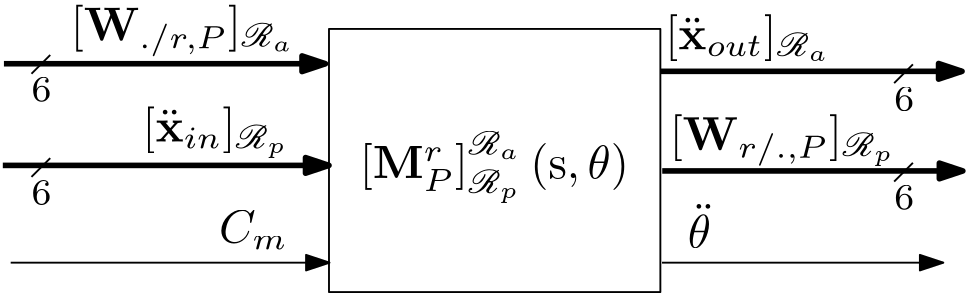

The angular configuration $\theta$ can be a varyring parameter declared with `ureal `so that the linear model derived from the SIMULINK model is valid for any angular configuration $\theta$.

Revolute joint can be also embedded inside the TITOP model of a rigid body, a flexible body and a flexible beam as it is proposed in the sub-library `Predefined subsystems `(see also the tutorial 6 of the** full version **of the `SDTlib`: [***a 6 dofs robotic arm on a chaser spacecraft***](matlab:open('../Tutorial6/tutorial6.html')) or  the tutorial 14: [***Kinematic and dynamic models and control of a planar 3 d.o.fs flexible arm***](matlab:open('../Tutorial14/tutorial14.html')) ) .

See also:

web DocRevoluteJoint_configuration.html -new

#### 2.2.2 Prismatic joint

Prismatic joint is now included in the **full version** of the `SDTlib.` The body $\mathcal A$ can be linked to the parent body $\mathcal P$ at point $P$ through a prismatic joint ($p$), characterized by the axis direction $\mathbf{t_a}$ and a translation configuration $x$. The point $P$ on the output slider of the prismatic joint coincides with the point $P_0$ on the input slider if $x=0$. The prismatic joint does not introduce change of frame and the model can be expressed in the inherit parent body frame $\mathcal R_p\equiv\mathcal R_a$. Then, the TITOP model of the prismatic joint $\left[\mathbf{M}^{p}_{P_0P}\right]_{\mathcal R_p}(\mathrm{s},x)$ depicted in the next Figure can be used for the assembly of the multi-body system. This block is a $13\times 13$ transfer with:

- the $12\times 12$ TITOP transfer between the wrenches and the accelerations twists at the point $P_0$ on the input slider and at the pont $P$ on the output slider,

- the SISO channel from the force $F_m$ applied inside the prismatic joint by a driving mechanism to the relative acceleration $\ddot x$ of the output slider w.r.t. the input slider.

                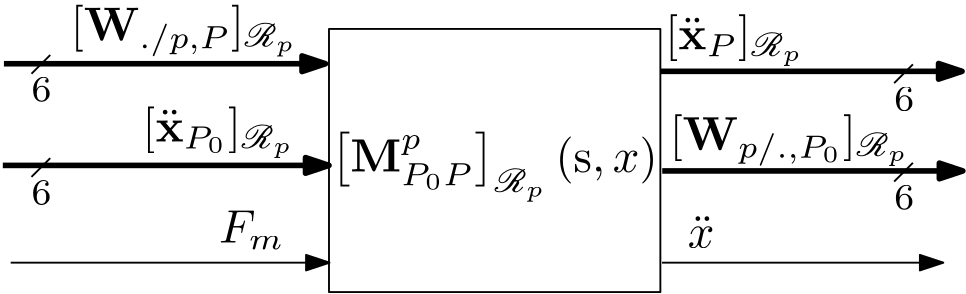

The translation configuration $x$ can be a varyring parameter declared with `ureal `so that the linear model derived from the SIMULINK model is valid for any configuration $x$ .

Prismatic joint can be also embedded inside the TITOP model of a rigid body as it is proposed in the sub-library `Predefined subsystems. S`ee also the tutorial 13 of the** full version **of the `SDTlib`:  [***the slider-crank mechanism***](matlab:open('../Tutorial13/tutorial13.html')) and

% web DocPrismatixJoint.html -new

### 2.3 Channel (port) inversion

Exactly as it was shown for the spring-mass system in the academic example above, the channels of the TITOP model of a flexible body $\mathcal A$ can be inverted to take into account boundary conditions:

- clamped at $P$  and clamped at $C$:  

                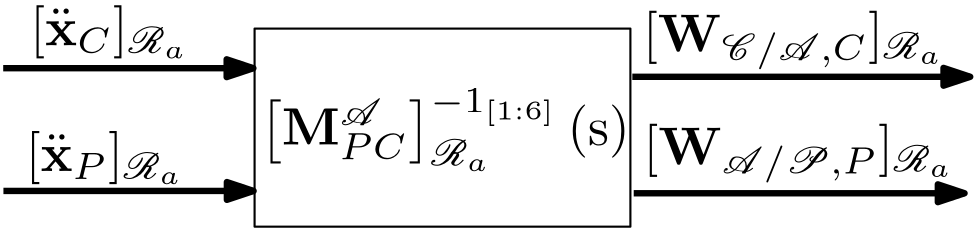

- free at $P$ and free at $C$:

                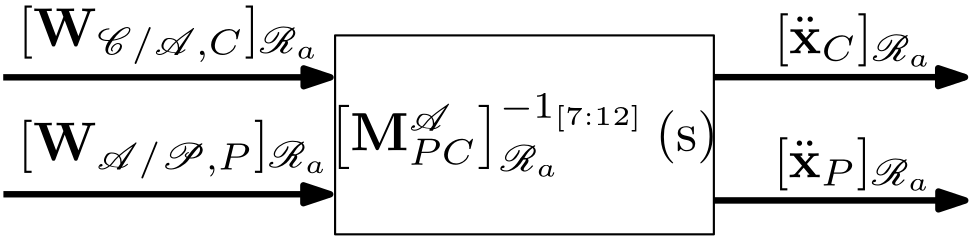

- free at $P$ and clamped at $C$:

                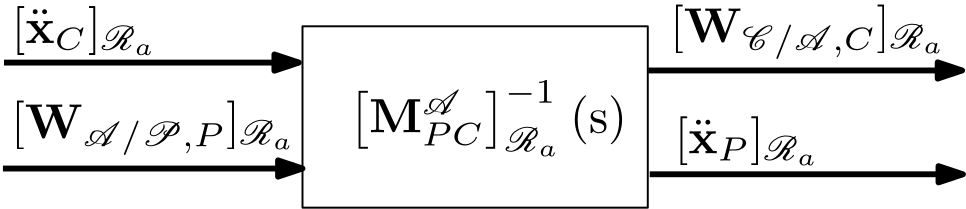

**Remark: **single or multiple channel inversions can be performed thanks to the function` invio` but these operations are not included in the dialog boxes of the various `SDTlib` blocks in its current version. But for the blocks:

- `Multi-port rigid body: `it is possible to inverse only **one** ( $6\times 6$ ) channel at one connection point or port (see: `port to be inverted` in the dialog box of the `Multi-port rigid body` block). Indeed for a rigid body, it is not possible to prescribe $2$ independent acceleration twists at 2 different points. Thus only one port can be inverted for a rigid body,

- `multi-port flexible plate: `it possible to specify up to $4$ parent points $P_i$, $i=1,\cdots 4$  where independent acceleration twists can be prescribed. See also the tutorial 9 of the** full version** of the `SDTLIB`: [***a solar array with 3 pannels***](matlab:open('../Tutorial9/tutorial9.html'))***.***

In the general case, for flexible bodies, there is no limits in the number of input/output channel which can be inverted. It is up to the user to manage these inversions by using the function `invio` and to create customized new blocks. See also the tutorial 11 of the** full version** of the `SDTLIB`: [***the 4 bar mechanism***](matlab:open('../Tutorial11/tutorial11.html'))`.`

### 2.4 Assembling open-kinematic chains with TITOP models

The connection of the body $\mathcal A$ in the whole structure between the parent body $\mathcal P$ and the child body $\mathcal C$ can be modelled by the interconnection of the TITOP models of the various bodies through the DCM (Direction Cosine Matrix) to manage the projection in the different  frames $\mathcal R_i$, $i=a,p,c$ where are described the bodies $\mathcal A$, $\mathcal P$ and $\mathcal C$, respectively.

In the following Figure,  $\mathbf P^{\times 2}_{i/j}=\left[\begin{array}{cc}\mathbf P_{i/j} & \mathbf 0_{3\times 3} \\ \mathbf 0_{3\times 3} & \mathbf P_{i/j}\end{array}\right]$ is the dual DCM and $\mathbf P_{i/j}$ is the $3\times 3$ DCM from frame $\mathcal R_i$ to frame $\mathcal R_j$, i.e:  the matrix where each column is the component vector of each orthogonal unit vector of $\mathcal R_i$ expressed in $\mathcal R_j$: $\forall\; \mathbf v\in \mathbb R^3,\;[\mathbf v]_{\mathcal R_j}=\mathbf P_{i/j}[\mathbf v]_{\mathcal R_i}$. See also:

web Doc6dcm.html -new

The bodies $\mathcal P$ and $\mathcal C$ can be also connected to some others bodies at some connection points ( $*$ ).

                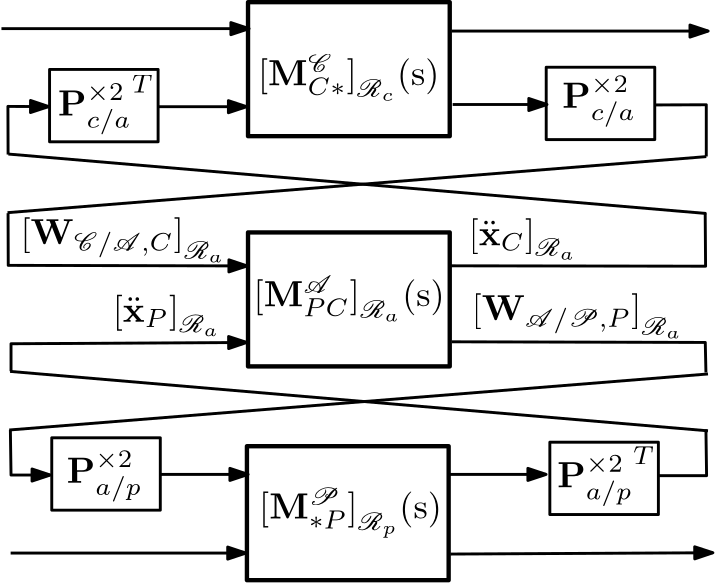

The tutorial 6 of the** full version** of the `SDTLIB` ([***a 6 dofs robotic arm on a chaser spacecraft***](matlab:open('../Tutorial6/tutorial6.html')) ) or the tutorial 14 ([***Kinematic and dynamic models and control of a planar 3 d.o.fs flexible arm***](matlab:open('../Tutorial14/tutorial14.html')) ) are representative  examples of multibody systems composed of  a serial connection of several rigid and flexible bodies based on this principle.

Since rigid and flexible bodies can also have several connections points $C_1$, $C_2$, $\cdots$ and be represented by NINOP model, it is also possible to model any kind of tree-like structures.

### 2.5 Assembling closed-kinematic chains with NINOP models

To assemble a closed-kinematics chain of bodies it is required to close the loop on a body with $2$ parent points as it was illustrated in the section Section 1.4. Thus:

- for rigid bodies, since their TITOP model cannot have more than 1 parent points (see remark), it is not possible to model directly a closed-kinematic chain composed only of rigid bodies. One can then close the loop using a `local stiffness` block from the `6 dof mechanism` sub-library (available only with the** full version** of the `SDTLIB)`. This block introduced $12$ states associated to $\delta\mathbf x$ and $\delta\dot\mathbf x$: the variation and the rate of variation of the stiffness strain along the 6 d.o.fs  (3 translations and 3 rotations). These states can be seen as the* Lagrange *multipliers commonly used to take into account  kinematics constraints.

- for flexible bodies, it is thus possible to build the model of a closed-kinematic chain mechanism thanks to the function `invio`. The user have to be sure that the mechanism have some stiffness on each of the 6 d.o.fs to absorb the closure constraints on the relative acceleration at the closure point ($\delta\ddot \mathbf x=\mathbf 0$).

Finally, although it is possible to derive a linear parametric model $\mathbf M(\mathrm s,\mathbf \theta)$ (i.e. an` uss` model)  of any open-kinematic chains of (rigid or flexible) bodies, parameterized according to the geometric configuration $\mathbf \theta$ (i.e. the vector of the rigid degrees of freedom of the system), it is not possible for mechanisms with closed-kinematics chain. Indeed, as mentionned in the introduction ([***tutorial 1***](matlab:open('../Tutorial1/tutorial1.html'))),  the SDTlib does not solve the non-linear loop closure constraints ( $\mathbf g(\mathbf \theta)=\mathbf 0$ ). If the user can provide a geometric configuration $\mathbf\theta_{ref}$ satisfying these constraints, then the SDTlib can be used to build a linear model which is valid for small variations around the configuration $\mathbf\theta_{ref}$ while satisfying the loop closure constraints at the acceleration level.

The tutorials with the** full version** of the `SDTLIB `dealing with closed-kinematic mechanisms:

- [***The 4 bar mechanism***](matlab:open('../Tutorial11/tutorial11.html')) (tutorial 11),

- [***A solar array with 3 pannels***](matlab:open('../Tutorial9/tutorial9.html')) (tutorial 9),

- [***The slider-crank mechanism***](matlab:open('../Tutorial13/tutorial13.html')) (tutorial 13)

## 3. References

To learn more on TITOP model: 

- Alazard, Daniel and Perez Gonzalez, José Alvaro and Loquen, Thomas and Cumer, Christelle.  [*Two-input two-output port model for mechanical systems.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/7666/two-input-two-output-port-model-for-mechanical-systems?_lg=en-US)     (2015) In: Scitech 2015 - 53rd AIAA Aerospace Sciences Meeting, 5 January 2015 - 9 January 2015  (Kissimmee, United States). 

- Murali H.H.S., Alazard D., Massotti L., Ankersen F., Toglia C. (2015)  Mechanical-Attitude Controller Co-design of Large Flexible Space Structures.  In: Bordeneuve-Guibé J., Drouin A., Roos C. (eds) Advances  in Aerospace Guidance, Navigation and Control. Springer, Cham.  [https://doi.org/10.1007/978-3-319-17518-8_38](https://doi.org/10.1007/978-3-319-17518-8_38)

- Perez Gonzalez, José Alvaro and Pittet, Christelle and Alazard, Daniel and Loquen, Thomas and Cumer, Christelle.  [*A Flexible Appendage Model for Use in Integrated Control/Structure Spacecraft Design.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/7729/a-flexible-appendage-model-for-use-in-integrated-control-structure-spacecraft-design)     (2015) In: 1st IFAC Workshop on Advanced Control and Navigation for  Autonomous Aerospace Vehicles (ACNAAV’15), 10 June 2015 - 12 June 2015   (Séville, Spain). 

- Perez Gonzalez, José Alvaro and Alazard, Daniel and Loquen, Thomas and Pittet, Christelle and Cumer, Christelle.  [*Flexible Multibody System Linear Modeling for Control Using Component Modes Synthesis and Double-Port Approach.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/3954/flexible-multibody-system-linear-modeling-for-control-using-component-modes-synthesis-and-double-por)     (2016) Journal of Dynamic Systems, Measurement, and Control, 138 (12).  121004. ISSN 0022-0434

- Chebbi, Jawhar and Dubanchet, Vincent and Perez Gonzalez, José Alvaro and Alazard, Daniel.  [*Linear dynamics of flexible multibody systems : a system-based approach.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/3719/linear-dynamics-of-flexible-multibody-systems-a-system-based-approach)     (2017) Multibody System Dynamics, 41 (1).  75-100. ISSN 1384-5640 

- Sanfedino, Francesco and Alazard, Daniel and Pommier-Budinger, Valérie and Falcoz, Alexandre and Boquet, Fabrice.  [*Finite element based N-Port model for preliminary design of multibody systems.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/3543/finite-element-based-n-port-model-for-preliminary-design-of-multibody-systems)     (2018) Journal of Sound and Vibration, 415.  128-146. ISSN 0022-460X

- Sanfedino, Francesco and Alazard, Daniel and Pommier-Budinger, Valérie and Boquet, Fabrice and Falcoz, Alexandre.  [*A novel dynamic model of a reaction wheel assembly for high accuracy pointing space missions.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/7089/a-novel-dynamic-model-of-a-reaction-wheel-assembly-for-high-accuracy-pointing-space-missions)     (2018) In: ASME 2018 Dynamic Systems and Control Conference (DSCC2018), 30  September 2018 - 3 October 2018  (Atlanta, United States).

- Murdoch, Naomi and Alazard, Daniel and Knapmeyer-Endrun, B. and Teanby, N. A. and Myhill, R..  [*Flexible Mode Modelling of the InSight Lander and Consequences for the SEIS Instrument.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/3301/flexible-mode-modelling-of-the-insight-lander-and-consequences-for-the-seis-instrument)     (2018) Space Science Reviews, 214 (117).  1-24. ISSN 0038-6308

- Sanfedino, Francesco, [Experimental validation of a high accuracy pointing system](https://depozit.isae.fr/theses/2019/2019_Sanfedino_Francesco_D.pdf), PhD. Thesis, Université de  Toulouse, ISAE-SUPAERO, 25 Avril 2019.

- Alazard, Daniel and Sanfedino, Francesco.  [*Satellite dynamics toolbox for preliminary design phase.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/6305/satellite-dynamics-toolbox-for-preliminary-design-phase)     (2020) In: 43rd Annual AAS Guidance and Control Conference, 30 January 2020 - 5 February 2020  (Brechenridge, United States). 